**Initial Setup**

clear all
close all
clc

directory = '../final_tests/Moving Darcy/primal/csv/';

files = struct2table(dir(append(directory, '*.csv')));
files = sortrows(files, 3);

**Import files**

shape = size(files);

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "y", "h"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
for j = 1:shape(1)
    name = files.name{j};
    data(j, :, :) = table2array(readtable(append(directory, name), opts));
end

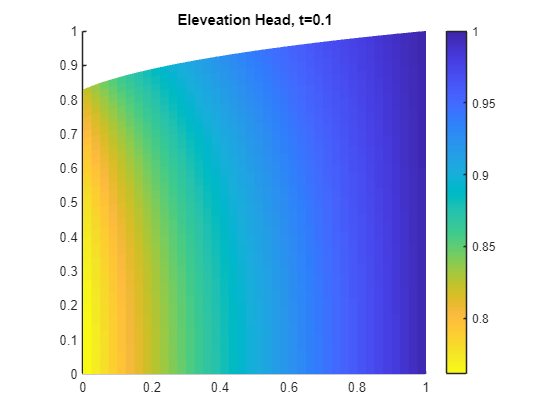

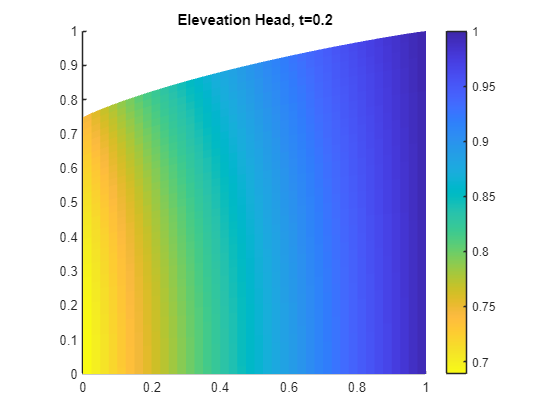

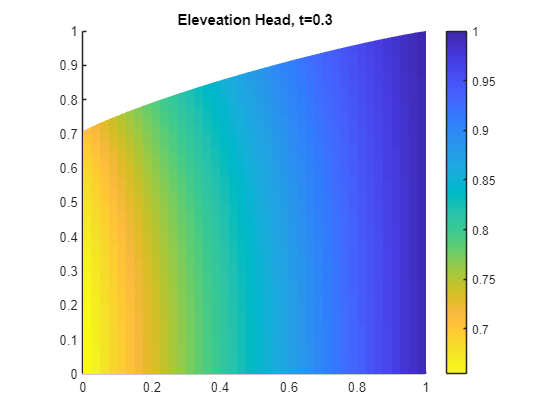

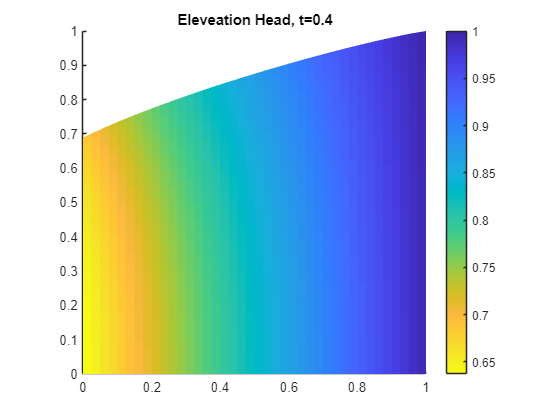

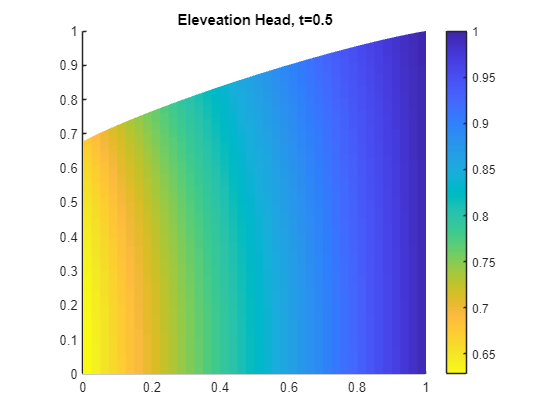

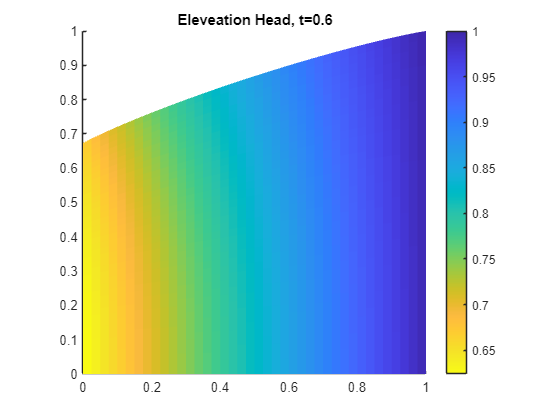

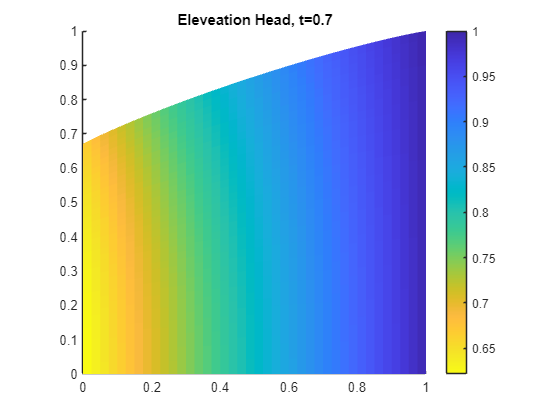

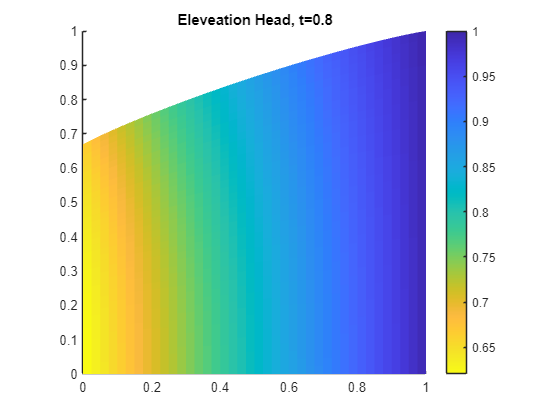

tmp = size( data(end, :, 1) );
N = sqrt(tmp(2));

for j = 1:shape(1)
    xq = reshape(data(j, :, 1), [N, N]);
    yq = reshape(data(j, :, 2), [N, N]);
    zq = reshape(data(j, :, 3), [N, N]);

    figure
    hold on
    surf(xq,yq,zq, 'EdgeColor','none')
    title(append('Eleveation Head, t=0.', append(string(j))))
    colormap(flipud(parula))
    colorbar
    axis tight
    daspect([5 5 1])
    hold off
end